% Step 1: Define System and Simulation Parameters
N = 64;              % Number of BS antennas
K = 4;               % Number of users
M = 4;               % Number of RF chains
omega = 0.3;         % Tradeoff weight

I_max = 60;          % Maximum outer iterations
J_values = [10, 20]; % Inner iteration counts
SNR_dB = 12;         % SNR in dB
sigma_n2 = 1;        % Noise variance
P_BS = sigma_n2 * 10^(SNR_dB / 10);  % Transmit power
mu = 0.01;           % Step size for analog precoder
lambda_ = 0.01;      % Step size for digital precoder
L = 20;              % Number of paths for channel
num_realizations = 2;% Number of channel realizations


% Step 2: Define Sensing Parameters
P = 3;                                   % Number of desired sensing angles
theta_d = [-60, 0, 60] * pi / 180;       % Desired angles in radians
delta_theta = 5 * pi / 180;              % Half beamwidth
theta_grid = linspace(-pi/2, pi/2, 181); % Angular grid [-90, 90] degrees
B_d = zeros(1, length(theta_grid));      % Desired beampattern

for t = 1:length(theta_grid)
    theta_t = theta_grid(t);
    for p = 1:length(theta_d)
        theta_p = theta_d(p);
        if abs(theta_t - theta_p) <= delta_theta
            B_d(t) = 1;
        end
    end
end

% Wavenumber and antenna spacing
lambda_wave = 1             % Wavelength (normalized)

lambda_wave = 1

k = 2 * pi / lambda_wave

k = 6.2832

d = lambda_wave / 2         % Antenna spacing

d = 0.5000

% Step 3: Generate the Channel

function H = generate_channel(N, M, L)
    % Constants (assuming half-wavelength antenna spacing)
    lambda = 1;           % Normalized wavelength
    d = lambda / 2;       % Antenna spacing
    k = 2 * pi / lambda;  % Wavenumber

    % Initialize channel
    H = complex(zeros(M, N));
    
    for l = 1:L
        % Complex Gaussian gain (Rayleigh fading)
        alpha_var = (randn + 1j * randn) / sqrt(2);
        
        % Random AoA and AoD
        phi_r = rand * 2 * pi;  % Angle of arrival
        phi_t = rand * 2 * pi;  % Angle of departure
        
        % Array response (steering) vectors
        a_r = exp(1j * k * d * (0:M-1).' * sin(phi_r)) / sqrt(M);
        a_t = exp(1j * k * d * (0:N-1).' * sin(phi_t)) / sqrt(N);
        
        % Add path contribution
        H = H + sqrt(N * M / L) * alpha_var * (a_r * a_t');
    end
end

% Step 4: Steering vector and the PSI

% Computes the steering vector for a given angle and number of antennas
function a = steering_vector(theta, N)
    lambda = 1;
    d = lambda / 2;
    k = 2 * pi / lambda;
    a = exp(1j * k * d * (0:N-1).' * sin(theta)) / sqrt(N);
end


function [Psi, alpha_var] = compute_psi(N, theta_grid, B_d, P_BS, f)
% COMPUTE_PSI_CVX  Estimate benchmark covariance matrix Psi using CVX optimization
%
% Inputs:
%   N           - Number of antennas (Nr)
%   theta_grid  - Vector of spatial grid angles [rad]
%   B_d         - Desired beampattern samples, length T
%   P_BS        - Total transmit power
%   f           - Optional constraint vectors (N x Nf), e.g., null steering directions
%
% Outputs:
%   Psi         - Optimal benchmark covariance matrix (N x N)
%   alpha       - Optimal scaling factor (scalar)
%
% This function solves:
%
%   minimize_{α, Ψ ≽ 0}  ∑_t | α·B_d(θ_t) − ā^H(θ_t)·Ψ·ā(θ_t) |²
%
%   subject to:
%       diag(Ψ) = P_BS / N
%       α ≥ 0
%       Ψ ≽ 0
%       f(:,n)' * Ψ * f(:,n) = 0 (optional null constraints)

    if nargin < 5
        f = [];  % No null constraints by default
    end

    T = length(theta_grid);
    Nr = N;

    % --- Construct steering matrix A (N x T)
    A = zeros(Nr, T);
    for t = 1:T
        A(:, t) = steering_vector(theta_grid(t), Nr);
    end

    % --- CVX optimization ---
    cvx_begin quiet
        variable R1(Nr, Nr) hermitian
        variable alpha_var nonnegative

        % Objective: minimize sum_t | α·B_d(t) − a_tᴴ·R1·a_t |²
        minimize( sum_square_abs(alpha_var .* B_d(:) - diag(A' * R1 * A)) );

        subject to
            % Equal power per antenna
            diag(R1) == (P_BS / Nr) * ones(Nr, 1);

            % Positive semi-definiteness
            R1 == semidefinite(Nr);

            % Optional null constraints
            if ~isempty(f)
                Nf = size(f, 2);
                for n = 1:Nf
                    trace(conj(f(:, n)) * transpose(f(:, n)) * R1) == 0;
                end
            end
    cvx_end

    Psi = R1;

end

Psi = compute_psi(N, theta_grid, B_d, P_BS);

function R = compute_rate(H, A, D, sigma_n2)
    H_A = H * A;               % Effective channel
    [~, K] = size(D);          % Number of users (columns of D)
    R = 0;

    for k = 1:K
        h_k = H_A(:, k);       % Channel to user k
        signal = abs(h_k' * D(:, k))^2;
        interference = 0;
        for j = 1:K
            if j ~= k
                interference = interference + abs(h_k' * D(:, j))^2;
            end
        end
        SINR = signal / (interference + sigma_n2);
        R = R + log2(1 + SINR);
    end
end

function tau = compute_tau(A, D, Psi, theta_grid)

    N = size(A, 1);
    V = A * D;
    T = length(theta_grid);

    tau = 0;
    for t = 1:T
        a_theta = steering_vector(theta_grid(t), N);
        term = a_theta' * (V * V' - Psi) * a_theta;
        tau = tau + abs(term)^2;
    end

    tau = tau / T;
end

function grad_A = gradient_R_A(H, A, D, sigma_n2)

    xi = 1 / log(2);                % Conversion factor from ln() to log2()
    grad_A = complex(zeros(size(A)));  % Initialize gradient
    V = D * D';                     % Effective covariance of digital precoder
    [K, ~] = size(H);               % Number of users

    for k = 1:K
        h_k = H(k, :).';            % Column vector (Nt x 1)
        H_tilde_k = h_k * h_k';     % Outer product (Nt x Nt)

        % D_bar_k = D with column k set to zero
        D_bar_k = D;
        D_bar_k(:, k) = 0;

        V_bar_k = D_bar_k * D_bar_k';

        % Denominators
        denom1 = trace(A * V * A' * H_tilde_k) + sigma_n2;
        denom2 = trace(A * V_bar_k * A' * H_tilde_k) + sigma_n2;

        % Gradient contribution
        term1 = H_tilde_k * A * V / denom1;
        term2 = H_tilde_k * A * V_bar_k / denom2;

        grad_A = grad_A + xi * (term1 - term2);
    end
end


function grad_D = gradient_R_D(H, A, D, sigma_n2)
    xi = 1 / log(2);
    grad_D = complex(zeros(size(D)));
    [K, ~] = size(H);

    for k = 1:K
        h_k = H(k, :).';            % (Nt x 1)
        H_tilde_k = h_k * h_k';     % (Nt x Nt)

        % Effective digital-domain channel
        H_bar_k = A' * H_tilde_k * A;   % (Ns x Ns)

        % D_bar_k = D with column k set to zero
        D_bar_k = D;
        D_bar_k(:, k) = 0;

        % Denominator terms
        denom1 = trace(D * D' * H_bar_k) + sigma_n2;
        denom2 = trace(D_bar_k * D_bar_k' * H_bar_k) + sigma_n2;

        % Gradient contributions
        term1 = (H_bar_k * D) / denom1;
        term2 = (H_bar_k * D_bar_k) / denom2;

        grad_D = grad_D + xi * (term1 - term2);
    end
end

function grad_A = gradient_tau_A(A, D, Psi)
    U = A * D * D' * A';           % A D Dᴴ Aᴴ
    grad_A = 2 * (U - Psi) * A * D * D';
end

function grad_D = gradient_tau_D(A, D, Psi)
    U = A * D * D' * A';           % A D Dᴴ Aᴴ
    grad_D = 2 * A' * (U - Psi) * A * D;
end

function [A0, D0] = proposed_initialization(H, theta_d, N, M, K, P_BS)

    G = H.';                              % (N x K)
    A0 = exp(-1j * angle(G(:, 1:M)));     % Phase-only projection

    X_ZF = pinv(H);                       % Zero-forcing baseband precoder
    D0 = pinv(A0) * X_ZF;                 % Digital precoder initialization

    % Power normalization
    D0 = sqrt(P_BS) * D0 / norm(A0 * D0, 'fro');
end

function [A0, D0] = random_initialization(N, M, H, P_BS)

    A0 = exp(1j * 2 * pi * rand(N, M));   % Random phase analog precoder
    D0 = pinv(H * A0);                    % Pseudoinverse-based digital precoder

    % Normalize transmit power
    D0 = sqrt(P_BS) * D0 / norm(A0 * D0, 'fro');
end

function [A0, D0] = svd_initialization(H, N, M, K, P_BS)

    [~, ~, V] = svd(H, 'econ');           % H = U*S*V', V is N x N
    A0 = V(:, 1:M);                       % Take first M right singular vectors
    A0 = exp(1j * angle(A0));             % Project to unit modulus (phase-only)

    H_A = H * A0;                         % Effective channel
    % Robust pseudoinverse (handles rank deficiency)
    if rcond(H_A) < 1e-8
        D0 = pinv(H_A + 1e-6 * eye(size(H_A)));
    else
        D0 = pinv(H_A);
    end

    % Power normalization
    D0 = sqrt(P_BS) * D0 / norm(A0 * D0, 'fro');
end

function objectives = run_pga(H, A0, D0, J, I_max, mu, lambda_, omega, sigma_n2, Psi, theta_grid, P_BS)
    [K, N] = size(H);          % H is K x N
    A = A0;
    D = D0;
    objectives = zeros(1, I_max);
    eta = 1 / N;               % Balancing term for gradient magnitudes

    for i = 1:I_max
        fprintf('\n===== Outer Iteration %d / %d =====\n', i, I_max);

        % ---- Inner Loop: Analog Precoder Update ----
        A_hat = A;
        for j = 1:J
            grad_R_A = gradient_R_A(H, A_hat, D, sigma_n2);
            grad_tau_A = gradient_tau_A(A_hat, D, Psi);

            % Gradient Ascent on A (Eq. 14b)
            grad_A = grad_R_A - omega * grad_tau_A;
            A_hat = A_hat + mu * grad_A;

            % Unit-modulus projection (Eq. 7)
            A_hat = exp(1j * angle(A_hat));
        end

        A = A_hat;  % Update analog precoder

        % ---- Digital Precoder Update ----
        grad_R_D = gradient_R_D(H, A, D, sigma_n2);
        grad_tau_D = gradient_tau_D(A, D, Psi);

        % Gradient Ascent on D (Eq. 15)
        grad_D = grad_R_D - omega * eta * grad_tau_D;
        D = D + lambda_ * grad_D;

        % Power constraint projection (Eq. 9)
        D = sqrt(P_BS) * D / norm(A * D, 'fro');

        % ---- Compute Objective ----
        R = compute_rate(H, A, D, sigma_n2);
        tau = compute_tau(A, D, Psi, theta_grid);
        objective = R - omega * tau;
        objectives(i) = objective;

        fprintf('Iteration %d: R = %.4f, τ = %.4e, Objective = %.4f\n', i, R, tau, objective);
    end
end

% ============================
% Step 6: Generate Plot (MATLAB)
% ============================

% Define containers for results
results = struct( ...
    'PGA_J10_Random', [], ...
    'PGA_J10_SVD', [], ...
    'PGA_J10_Proposed', [], ...
    'PGA_J20_Random', [], ...
    'PGA_J20_SVD', [], ...
    'PGA_J20_Proposed', [], ...
    'UPGANet_J10_Proposed', [], ...
    'UPGANet_J20_Proposed', [] );

% Loop over realizations
for r = 1:num_realizations
    fprintf('\n=== Channel Realization %d / %d ===\n', r, num_realizations);
    H = generate_channel(N, M, L);  % User-defined channel generator

    for J = J_values
        fprintf('\n--- Inner iterations: J = %d ---\n', J);

        % ---------- Random Initialization ----------
        [A0, D0] = random_initialization(N, M, H, P_BS);
        objectives = run_pga(H, A0, D0, J, I_max, mu, lambda_, omega, sigma_n2, Psi, theta_grid, P_BS);
        results.(sprintf('PGA_J%d_Random', J)){r} = objectives;
        fprintf('Completed PGA with J=%d using Random Initialization\n', J);

        % ---------- SVD Initialization ----------
        [A0, D0] = svd_initialization(H, N, M, K, P_BS);
        objectives = run_pga(H, A0, D0, J, I_max, mu, lambda_, omega, sigma_n2, Psi, theta_grid, P_BS);
        results.(sprintf('PGA_J%d_SVD', J)){r} = objectives;
        fprintf('Completed PGA with J=%d using SVD Initialization\n', J);

        % ---------- Proposed Initialization ----------
        [A0, D0] = proposed_initialization(H, theta_d, N, M, K, P_BS);
        objectives = run_pga(H, A0, D0, J, I_max, mu, lambda_, omega, sigma_n2, Psi, theta_grid, P_BS);
        results.(sprintf('PGA_J%d_Proposed', J)){r} = objectives;
        fprintf('Completed PGA with J=%d using Proposed Initialization\n', J);

        % ---------- UPGANet (Simulated) ----------
        objectives = run_pga(H, A0, D0, J, I_max, 1.5*mu, 1.5*lambda_, omega, sigma_n2, Psi, theta_grid, P_BS);
        results.(sprintf('UPGANet_J%d_Proposed', J)){r} = objectives;
        fprintf('Completed UPGANet simulation with J=%d using Proposed Initialization\n', J);
    end
end


=== Channel Realization 1 / 2 ===



--- Inner iterations: J = 10 ---



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 2.9115, τ = 2.1226e-01, Objective = 2.8478

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 2.7885, τ = 2.0889e-01, Objective = 2.7258

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 3.4537, τ = 2.0957e-01, Objective = 3.3908

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 2.9318, τ = 2.0790e-01, Objective = 2.8695

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.6527, τ = 2.0997e-01, Objective = 3.5897

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 2.8323, τ = 2.0507e-01, Objective = 2.7708

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.7013, τ = 2.0686e-01, Objective = 3.6393

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.7433, τ = 2.0154e-01, Objective = 2.6828

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 3.7655, τ = 2.0402e-01, Objective = 3.7043

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.7349, τ = 1.9851e-01, Objective = 2.6753

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using Random Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 3.7984, τ = 6.2092e-01, Objective = 3.6121

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 4.4797, τ = 6.1355e-01, Objective = 4.2956

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 5.1672, τ = 5.9732e-01, Objective = 4.9880

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 5.5910, τ = 5.7340e-01, Objective = 5.4190

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 5.4689, τ = 5.4404e-01, Objective = 5.3057

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 4.9249, τ = 5.1365e-01, Objective = 4.7708

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 4.2188, τ = 4.8937e-01, Objective = 4.0720

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 3.4858, τ = 4.7506e-01, Objective = 3.3433

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.8060, τ = 4.6318e-01, Objective = 2.6671

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.1996, τ = 4.5037e-01, Objective = 2.0645

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using SVD Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 8.1052, τ = 3.4480e-01, Objective = 8.0018

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 4.6261, τ = 3.5559e-01, Objective = 4.5195

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 3.3529, τ = 3.6574e-01, Objective = 3.2432

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 3.8416, τ = 3.5879e-01, Objective = 3.7339

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.1417, τ = 3.5357e-01, Objective = 3.0356

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 3.7562, τ = 3.7850e-01, Objective = 3.6427

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 2.4604, τ = 3.6002e-01, Objective = 2.3524

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 3.4509, τ = 4.2596e-01, Objective = 3.3231

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.2955, τ = 3.6570e-01, Objective = 2.1858

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 3.0975, τ = 4.6607e-01, Objective = 2.9577

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using Proposed Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 6.2621, τ = 3.5194e-01, Objective = 6.1565

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 3.1342, τ = 3.7177e-01, Objective = 3.0227

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 4.2354, τ = 3.5598e-01, Objective = 4.1286

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 2.3947, τ = 3.6457e-01, Objective = 2.2854

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.6856, τ = 4.8680e-01, Objective = 3.5396

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 2.3428, τ = 3.3972e-01, Objective = 2.2409

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 2.9432, τ = 5.3725e-01, Objective = 2.7820

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.1981, τ = 3.5301e-01, Objective = 2.0922

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.7319, τ = 5.6501e-01, Objective = 2.5624

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.2128, τ = 3.5235e-01, Objective = 2.1071

===== Outer Iteration 11 / 60 =====
I

Completed UPGANet simulation with J=10 using Proposed Initialization



--- Inner iterations: J = 20 ---



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 0.9104, τ = 1.9918e-01, Objective = 0.8507

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 0.8669, τ = 2.0374e-01, Objective = 0.8057

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 0.9746, τ = 2.1160e-01, Objective = 0.9111

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 1.0901, τ = 2.1193e-01, Objective = 1.0266

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 1.2641, τ = 2.1752e-01, Objective = 1.1988

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 1.3053, τ = 2.1006e-01, Objective = 1.2423

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 1.4903, τ = 2.1163e-01, Objective = 1.4268

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 1.3579, τ = 2.0574e-01, Objective = 1.2962

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 1.4731, τ = 1.9974e-01, Objective = 1.4132

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 1.3035, τ = 1.9700e-01, Objective = 1.2444

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using Random Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 3.8125, τ = 6.1831e-01, Objective = 3.6271

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 4.5267, τ = 6.0674e-01, Objective = 4.3447

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 5.2409, τ = 5.8508e-01, Objective = 5.0653

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 5.5503, τ = 5.5532e-01, Objective = 5.3837

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 5.1307, τ = 5.2181e-01, Objective = 4.9742

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 4.3115, τ = 4.9256e-01, Objective = 4.1637

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.4160, τ = 4.7355e-01, Objective = 3.2740

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.6024, τ = 4.5876e-01, Objective = 2.4648

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 1.9521, τ = 4.5052e-01, Objective = 1.8169

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 1.5264, τ = 4.5039e-01, Objective = 1.3912

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using SVD Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 7.7471, τ = 3.4021e-01, Objective = 7.6451

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 4.2871, τ = 3.4652e-01, Objective = 4.1832

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 3.8939, τ = 3.4356e-01, Objective = 3.7908

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 3.9760, τ = 3.4283e-01, Objective = 3.8732

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.4983, τ = 3.4814e-01, Objective = 3.3939

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 3.5875, τ = 3.5887e-01, Objective = 3.4798

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 2.9646, τ = 3.7014e-01, Objective = 2.8535

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 3.0146, τ = 3.8392e-01, Objective = 2.8994

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.8010, τ = 4.4804e-01, Objective = 2.6666

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.7623, τ = 4.1007e-01, Objective = 2.6393

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using Proposed Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 5.7772, τ = 3.4502e-01, Objective = 5.6737

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 3.2577, τ = 3.4678e-01, Objective = 3.1536

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 4.5398, τ = 3.6079e-01, Objective = 4.4315

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 2.4446, τ = 3.5910e-01, Objective = 2.3369

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.4960, τ = 4.5226e-01, Objective = 3.3603

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 2.5403, τ = 4.0717e-01, Objective = 2.4182

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 2.9742, τ = 5.1693e-01, Objective = 2.8191

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.7556, τ = 3.6750e-01, Objective = 2.6454

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.7402, τ = 4.9463e-01, Objective = 2.5918

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 3.0117, τ = 3.7994e-01, Objective = 2.8978

===== Outer Iteration 11 / 60 =====
I

Completed UPGANet simulation with J=20 using Proposed Initialization



=== Channel Realization 2 / 2 ===



--- Inner iterations: J = 10 ---



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 2.6834, τ = 2.2579e-01, Objective = 2.6157

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 2.8572, τ = 2.2265e-01, Objective = 2.7904

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 3.0991, τ = 2.1979e-01, Objective = 3.0332

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 3.5155, τ = 2.1663e-01, Objective = 3.4505

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 4.1166, τ = 2.1298e-01, Objective = 4.0527

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 4.2262, τ = 2.1347e-01, Objective = 4.1622

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.6907, τ = 2.1205e-01, Objective = 3.6271

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 4.2470, τ = 2.1440e-01, Objective = 4.1826

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 3.3693, τ = 2.1270e-01, Objective = 3.3054

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 4.0834, τ = 2.1292e-01, Objective = 4.0196

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using Random Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 0.2860, τ = 4.3155e-01, Objective = 0.1565

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 0.2410, τ = 4.0846e-01, Objective = 0.1185

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 0.2217, τ = 3.8750e-01, Objective = 0.1055

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 0.2261, τ = 3.6941e-01, Objective = 0.1153

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 0.2504, τ = 3.5456e-01, Objective = 0.1440

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 0.2887, τ = 3.4288e-01, Objective = 0.1858

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 0.3337, τ = 3.3395e-01, Objective = 0.2335

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 0.3797, τ = 3.2727e-01, Objective = 0.2816

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 0.4247, τ = 3.2240e-01, Objective = 0.3280

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 0.4683, τ = 3.1902e-01, Objective = 0.3726

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using SVD Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 9.1466, τ = 2.2646e-01, Objective = 9.0786

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 8.0558, τ = 2.3063e-01, Objective = 7.9866

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 6.8454, τ = 2.3703e-01, Objective = 6.7743

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 5.8302, τ = 2.4458e-01, Objective = 5.7568

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 5.0308, τ = 2.5195e-01, Objective = 4.9552

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 4.4294, τ = 2.5819e-01, Objective = 4.3519

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.9985, τ = 2.6268e-01, Objective = 3.9197

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 3.6946, τ = 2.6495e-01, Objective = 3.6152

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 3.4682, τ = 2.6476e-01, Objective = 3.3888

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 3.2819, τ = 2.6226e-01, Objective = 3.2032

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=10 using Proposed Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 8.6331, τ = 2.2869e-01, Objective = 8.5645

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 6.8302, τ = 2.3840e-01, Objective = 6.7587

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 5.4175, τ = 2.5032e-01, Objective = 5.3425

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 4.4417, τ = 2.6009e-01, Objective = 4.3637

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.8356, τ = 2.6612e-01, Objective = 3.7558

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 3.4783, τ = 2.6743e-01, Objective = 3.3981

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.2162, τ = 2.6351e-01, Objective = 3.1371

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.9810, τ = 2.5550e-01, Objective = 2.9043

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.7582, τ = 2.4539e-01, Objective = 2.6846

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.5446, τ = 2.3493e-01, Objective = 2.4741

===== Outer Iteration 11 / 60 =====
I

Completed UPGANet simulation with J=10 using Proposed Initialization



--- Inner iterations: J = 20 ---



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 1.3012, τ = 2.3800e-01, Objective = 1.2298

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 1.1028, τ = 2.3333e-01, Objective = 1.0328

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 1.0810, τ = 2.2507e-01, Objective = 1.0135

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 1.1301, τ = 2.1941e-01, Objective = 1.0643

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 1.0723, τ = 2.1982e-01, Objective = 1.0063

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 0.9508, τ = 2.2112e-01, Objective = 0.8845

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 0.9360, τ = 2.2351e-01, Objective = 0.8690

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 0.8465, τ = 2.2476e-01, Objective = 0.7790

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 0.8760, τ = 2.2600e-01, Objective = 0.8082

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 0.7995, τ = 2.2449e-01, Objective = 0.7322

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using Random Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 0.2867, τ = 4.3556e-01, Objective = 0.1561

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 0.2459, τ = 4.1443e-01, Objective = 0.1216

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 0.2353, τ = 3.9371e-01, Objective = 0.1172

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 0.2527, τ = 3.7461e-01, Objective = 0.1404

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 0.2923, τ = 3.5800e-01, Objective = 0.1849

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 0.3451, τ = 3.4398e-01, Objective = 0.2419

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 0.4022, τ = 3.3191e-01, Objective = 0.3026

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 0.4554, τ = 3.2109e-01, Objective = 0.3591

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 0.5055, τ = 3.1231e-01, Objective = 0.4118

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 0.5664, τ = 3.0623e-01, Objective = 0.4746

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using SVD Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 9.0184, τ = 2.2550e-01, Objective = 8.9508

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 7.8406, τ = 2.2898e-01, Objective = 7.7719

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 6.6437, τ = 2.3410e-01, Objective = 6.5735

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 5.6578, τ = 2.3846e-01, Objective = 5.5862

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 4.8657, τ = 2.4055e-01, Objective = 4.7935

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 4.2553, τ = 2.3999e-01, Objective = 4.1833

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 3.8067, τ = 2.3667e-01, Objective = 3.7357

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 3.4662, τ = 2.3064e-01, Objective = 3.3970

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 3.1768, τ = 2.2250e-01, Objective = 3.1101

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 2.9089, τ = 2.1328e-01, Objective = 2.8449

===== Outer Iteration 11 / 60 =====
I

Completed PGA with J=20 using Proposed Initialization



===== Outer Iteration 1 / 60 =====
Iteration 1: R = 8.4418, τ = 2.2763e-01, Objective = 8.3735

===== Outer Iteration 2 / 60 =====
Iteration 2: R = 6.6245, τ = 2.3629e-01, Objective = 6.5536

===== Outer Iteration 3 / 60 =====
Iteration 3: R = 5.2620, τ = 2.4255e-01, Objective = 5.1892

===== Outer Iteration 4 / 60 =====
Iteration 4: R = 4.2835, τ = 2.4270e-01, Objective = 4.2107

===== Outer Iteration 5 / 60 =====
Iteration 5: R = 3.6629, τ = 2.3727e-01, Objective = 3.5918

===== Outer Iteration 6 / 60 =====
Iteration 6: R = 3.2397, τ = 2.2633e-01, Objective = 3.1718

===== Outer Iteration 7 / 60 =====
Iteration 7: R = 2.8520, τ = 2.1232e-01, Objective = 2.7883

===== Outer Iteration 8 / 60 =====
Iteration 8: R = 2.4839, τ = 1.9910e-01, Objective = 2.4241

===== Outer Iteration 9 / 60 =====
Iteration 9: R = 2.1341, τ = 1.9027e-01, Objective = 2.0770

===== Outer Iteration 10 / 60 =====
Iteration 10: R = 1.8747, τ = 1.8711e-01, Objective = 1.8186

===== Outer Iteration 11 / 60 =====
I

Completed UPGANet simulation with J=20 using Proposed Initialization


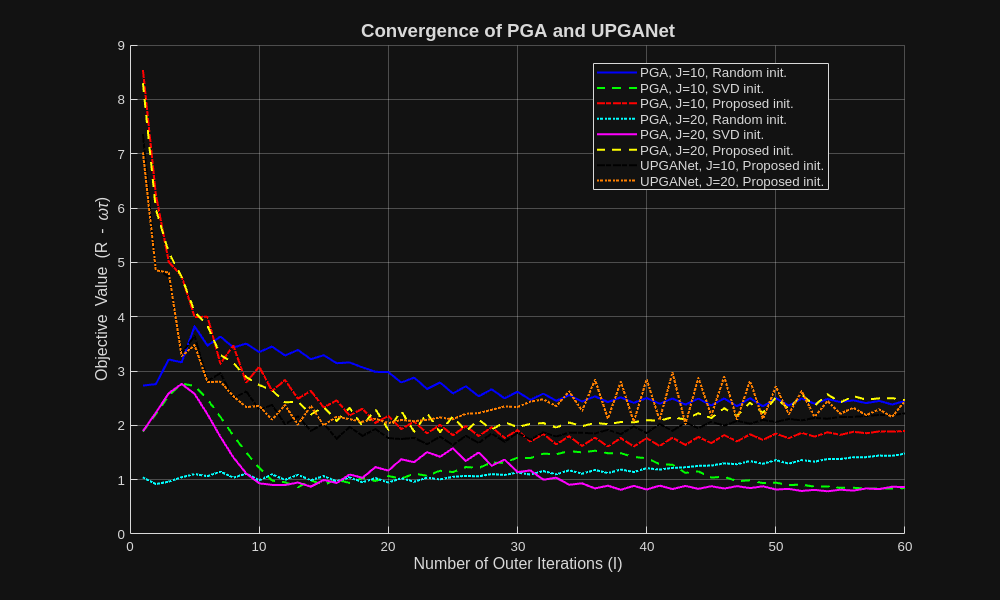


% ---------- Compute Average Results ----------
avg_results = struct();
fields = fieldnames(results);

for i = 1:length(fields)
    key = fields{i};
    val = results.(key);
    % Convert cell array to matrix and average across realizations
    mat = cell2mat(val');
    avg_results.(key) = mean(mat, 1);
end

% ---------- Plot Results ----------
figure('Position', [200, 200, 1000, 600]);
colors = {'b', 'g', 'r', 'c', 'm', 'y', 'k', [1, 0.5, 0]}; % orange = [1, 0.5, 0]
styles = {'-', '--', '-.', ':', '-', '--', '-.', ':'};
labels = { ...
    'PGA, J=10, Random init.', ...
    'PGA, J=10, SVD init.', ...
    'PGA, J=10, Proposed init.', ...
    'PGA, J=20, Random init.', ...
    'PGA, J=20, SVD init.', ...
    'PGA, J=20, Proposed init.', ...
    'UPGANet, J=10, Proposed init.', ...
    'UPGANet, J=20, Proposed init.' };

hold on;
for idx = 1:length(fields)
    key = fields{idx};
    plot(1:I_max, real(avg_results.(key)), 'Color', colors{idx}, ...
         'LineStyle', styles{idx}, 'LineWidth', 1.5, 'DisplayName', labels{idx});
end
hold off;

xlabel('Number of Outer Iterations (I)', 'FontSize', 12);
ylabel('Objective Value (R - \omega\tau)', 'FontSize', 12);
title('Convergence of PGA and UPGANet', 'FontSize', 14);
legend('Location', 'best', 'FontSize', 10);
grid on;